## Condiciones iniciales de avance

clear

syms a1(t) a2(t) a3(t) a4(t) a5(t) T A
syms v1(t) v2(t) v3(t) v4(t) v5(t) 
syms x1(t) x2(t) x3(t) x4(t) x5(t)
assume(T>0)
assume(A>0)
g=9.81;
xMax=0.1

xMax = 0.1000

aMax=g/6

aMax = 1.6350

A=aMax;


## Aceleración

a1(t)=10*A/T*t;

a2(t)=A;

a3(t)=-10*A/T*t;
Ca3=A-a3(4*T/10);
a3(t)=a3(t)+Ca3;
a4(t)=-A;
a5(t)=10*A/T*t;
Ca5=a4(9*T/10)-a5(9*T/10);
a5(t)=a5(t)+Ca5;
fprintf('Función de aceleración:')

Función de aceleración:

a(t)=piecewise((0<=t<T/10),a1,(T/10<=t<4*T/10),a2,(4*T/10<=t<6*T/10),a3,(6*T/10<=t<9*T/10),a4,(9*T/10<=t<=T),a5)

$$a(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{327}{200} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ \frac{327}{40}-\sigma_{1} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ -\frac{327}{200} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \sigma_{1}-\frac{327}{20} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{327\,t}{20\,T} \end{array}$$

## Velocidad

v1(t)=int(a1);

v2(t)=int(a2);
Cv2=v1(T/10)-v2(T/10);
v2(t)=v2(t)+Cv2;

v3(t)=int(a3);
Cv3=v2(4*T/10)-v3(4*T/10);
v3(t)=v3(t)+Cv3;

v4(t)=int(a4);
Cv4=v3(6*T/10)-v4(6*T/10);
v4(t)=v4(t)+Cv4;

v5(t)=int(a5);
Cv5=v4(9*T/10)-v5(9*T/10);
v5(t)=v5(t)+Cv5;

fprintf('Función de velocidad:')

Función de velocidad:

v(t)=piecewise((0<=t<T/10),v1,(T/10<=t<4*T/10),v2,(4*T/10<=t<6*T/10),v3,(6*T/10<=t<9*T/10),v4,(9*T/10<=t<=T),v5)

$$v(t) = \left\{ \begin{array}{cl} \frac{327\,t^{2}}{40\,T} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{327\,t}{200}-\frac{327\,T}{4000} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ -\frac{5559\,T}{4000}-\frac{t\,\left(\frac{327\,t}{T}-327\right)}{40} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ \frac{6213\,T}{4000}-\frac{327\,t}{200} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \frac{327\,T}{40}+\frac{t\,\left(\frac{327\,t}{2\,T}-327\right)}{20} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.$$

## Desplazamiento


x1(t)=int(v1);

x2(t)=int(v2);
Cx2=x1(T/10)-x2(T/10);
x2(t)=x2(t)+Cx2;

x3(t)=int(v3);
Cx3=x2(4*T/10)-x3(4*T/10);
x3(t)=x3(t)+Cx3;

x4(t)=int(v4);
Cx4=x3(6*T/10)-x4(6*T/10);
x4(t)=x4(t)+Cx4;

x5(t)=int(v5);
Cx5=x4(9*T/10)-x5(9*T/10);
x5(t)=x5(t)+Cx5;

fprintf('Función de desplazamiento:')

Función de desplazamiento:

x(t)=piecewise((0<=t<T/10),x1,(T/10<=t<4*T/10),x2,(4*T/10<=t<6*T/10),x3,(6*T/10<=t<9*T/10),x4,(9*T/10<=t<=T),x5)

$$x(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{109\,T^{2}}{40000}-\frac{327\,t\,\left(T-10\,t\right)}{4000} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ \frac{1417\,T^{2}}{8000}-\frac{5559\,T\,t}{4000}+\frac{327\,t^{2}}{80}-\sigma_{1} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ \frac{327\,t\,\left(19\,T-10\,t\right)}{4000}-\frac{16459\,T^{2}}{40000} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \frac{109\,t\,\left(3\,T^{2}-3\,T\,t+t^{2}\right)}{40\,T}-\frac{1199\,T^{2}}{500} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{109\,t^{3}}{40\,T} \end{array}$$

## Solución de tMax

f=xMax/2==x(T/2);

tMax=solve(f,T);


a=subs(a,T,tMax);
v=subs(v,T,tMax);
x=subs(x,T,tMax);
a(t)=piecewise((0<=t<tMax),a(t),(tMax<=t<=2*tMax),-a(t-tMax))

$$a(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }t\in \left[0,\frac{\sqrt{327}}{327}\right)\\ \frac{327}{200} & \text{ if }t\in \left[\frac{\sqrt{327}}{327},\sigma_{6}\right)\\ \frac{327}{40}-\sigma_{1} & \text{ if }t\in \left[\sigma_{6},\sigma_{8}\right)\\ -\frac{327}{200} & \text{ if }t\in \left[\sigma_{8},\sigma_{7}\right)\\ \sigma_{1}-\frac{327}{20} & \text{ if }t\in \left[\sigma_{7},\sigma_{10}\right)\\ -\sigma_{9} & \text{ if }t\in \left[\sigma_{10},\sigma_{5}\right)\\ -\frac{327}{200} & \text{ if }t\in \left[\sigma_{5},\sigma_{4}\right)\\ \sigma_{9}-\frac{327}{40} & \text{ if }t\in \left[\sigma_{4},\sigma_{3}\right)\\ \frac{327}{200} & \text{ if }t\in \left[\sigma_{3},\sigma_{2}\right)\\ \frac{327}{20}-\sigma_{9} & \text{ if }\sigma_{2}\leq t\wedge t\leq \frac{20\,\sqrt{327}}{327} \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{327\,\sqrt{327}\,t}{200}\\ \sigma_{2}=\frac{19\,\sqrt{327}}{327}\\ \sigma_{3}=\frac{16\,\sqrt{327}}{327}\\ \sigma_{4}=\frac{14\,\sqrt{327}}{327}\\ \sigma_{5}=\frac{11\,\sqrt{327}}{327}\\ \sigma_{6}=\frac{4\,\sqrt{327}}{327}\\ \sigma_{7}=\frac{3\,\sqrt{327}}{109}\\ \sigma_{8}=\frac{2\,\sqrt{327}}{109}\\ \sigma_{9}=\frac{327\,\sqrt{327}\,\left(t-\sigma_{10}\right)}{200}\\ \sigma_{10}=\frac{10\,\sqrt{327}}{327} \end{array}$$

v(t)=piecewise((0<=t<tMax),v(t),(tMax<=t<=2*tMax),-v(t-tMax))

$$v(t) = \begin{array}{l} \left\{ \begin{array}{cl} \frac{327\,\sqrt{327}\,t^{2}}{400} & \text{ if }t\in \left[0,\frac{\sqrt{327}}{327}\right)\\ \frac{327\,t}{200}-\frac{\sqrt{327}}{400} & \text{ if }t\in \left[\frac{\sqrt{327}}{327},\sigma_{6}\right)\\ -\sigma_{1}-\frac{t\,\left(\frac{327\,\sqrt{327}\,t}{10}-327\right)}{40} & \text{ if }t\in \left[\sigma_{6},\sigma_{8}\right)\\ \frac{19\,\sqrt{327}}{400}-\frac{327\,t}{200} & \text{ if }t\in \left[\sigma_{8},\sigma_{7}\right)\\ \frac{\sqrt{327}}{4}+\frac{t\,\left(\frac{327\,\sqrt{327}\,t}{20}-327\right)}{20} & \text{ if }t\in \left[\sigma_{7},\sigma_{10}\right)\\ -\frac{327\,\sqrt{327}\,{\left(t-\sigma_{10}\right)}^{2}}{400} & \text{ if }t\in \left[\sigma_{10},\sigma_{5}\right)\\ \frac{21\,\sqrt{327}}{400}-\frac{327\,t}{200} & \text{ if }t\in \left[\sigma_{5},\sigma_{4}\right)\\ \sigma_{1}+\frac{\left(t-\sigma_{10}\right)\,\left(\frac{\sigma_{9}}{10}-327\right)}{40} & \text{ if }t\in \left[\sigma_{4},\sigma_{3}\right)\\ \frac{327\,t}{200}-\frac{39\,\sqrt{327}}{400} & \text{ if }t\in \left[\sigma_{3},\sigma_{2}\right)\\ -\frac{\sqrt{327}}{4}-\frac{\left(t-\sigma_{10}\right)\,\left(\frac{\sigma_{9}}{20}-327\right)}{20} & \text{ if }\sigma_{2}\leq t\wedge t\leq \frac{20\,\sqrt{327}}{327} \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{17\,\sqrt{327}}{400}\\ \sigma_{2}=\frac{19\,\sqrt{327}}{327}\\ \sigma_{3}=\frac{16\,\sqrt{327}}{327}\\ \sigma_{4}=\frac{14\,\sqrt{327}}{327}\\ \sigma_{5}=\frac{11\,\sqrt{327}}{327}\\ \sigma_{6}=\frac{4\,\sqrt{327}}{327}\\ \sigma_{7}=\frac{3\,\sqrt{327}}{109}\\ \sigma_{8}=\frac{2\,\sqrt{327}}{109}\\ \sigma_{9}=327\,\sqrt{327}\,\left(t-\sigma_{10}\right)\\ \sigma_{10}=\frac{10\,\sqrt{327}}{327} \end{array}$$

x(t)=piecewise((0<=t<tMax),x(t),(tMax<=t<=2*tMax),x(tMax)-x(t-tMax))

tMax=2*tMax;
fprintf('Tiempo de ciclo %.3f s',tMax)

Tiempo de ciclo 1.106 s

## Gráficas

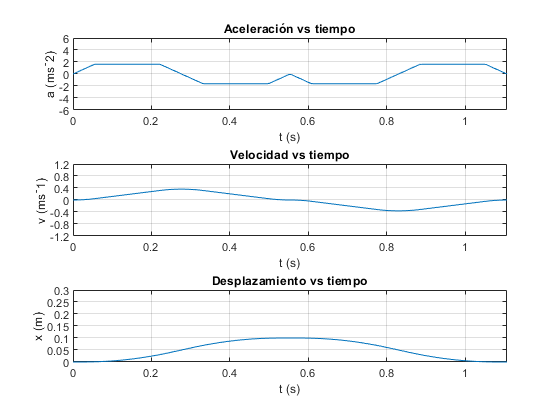

ts=linspace(0,tMax,200);
subplot(3,1,1)

plot(ts,a(ts))
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (ms^-2)')
ylim([-6 6])
xlim([0 double(tMax)])
yticks(-6:2:6)


subplot(3,1,2)

plot(ts,v(ts))
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (ms^-1)')
ylim([-1.2 1.2])
xlim([0 double(tMax)])
yticks(-1.2:0.4:1.2)

subplot(3,1,3)

plot(ts,x(ts))
title('Desplazamiento vs tiempo')
grid on
xlabel('t (s)')
ylabel('x (m)')
ylim([0 0.30])
xlim([0 double(tMax)])
yticks(0:0.05:0.30)






%MAA=table(double(ts'),double(x(ts)')*1000)

%writetable(MAA,'docTXT/MAvance.txt','delimiter',' ', 'WriteVariableNames', true)





## Tranformación movimiento lineal a radial


Velocidad_Linear_Max=0.75

Velocidad_Linear_Max = 0.7500

Velocidad_Radial_Max_RPM=1800

Velocidad_Radial_Max_RPM = 1800

Velocidad_Radial_Max_rads=Velocidad_Radial_Max_RPM*pi/30

Velocidad_Radial_Max_rads = 188.4956


Razon_VR_VL=Velocidad_Radial_Max_rads/Velocidad_Linear_Max

Razon_VR_VL = 251.3274



aRadial=double(a(ts)*Razon_VR_VL);
vRadial=double(v(ts)*Razon_VR_VL);
xRadial=double(x(ts)*Razon_VR_VL);


vRadial2=vRadial*30/pi

vRadial2 =          0    1.0959    4.3837    9.8633   17.5347   27.3980   39.4531   53.7001   70.1389   88.7695  109.5893  131.3981  153.2069  175.0157  196.8245  218.6334  240.4422  262.2510  284.0598  305.8686  327.6774  349.4862  371.2951  393.1039  414.9127  436.7215  458.5303  480.3391  502.1479  523.9567  545.7656  567.5744  589.3832  611.1920  633.0008  654.8096  676.6184  698.4273  720.2361  742.0449  763.8099  784.0844  802.1671  818.0579  831.7569  843.2641  852.5794  859.7029  864.6345  867.3743


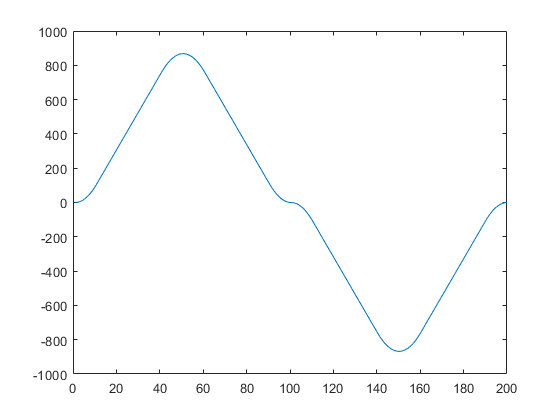


figure()
plot(vRadial2)

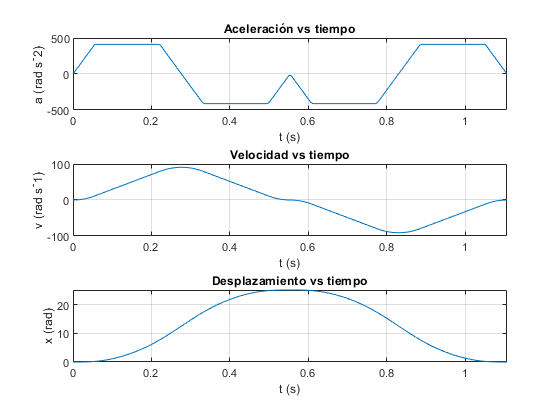



figure()
subplot(3,1,1)

plot(ts,aRadial)
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (rad s^-2)')
xlim([0 double(tMax)])

subplot(3,1,2)
plot(ts,vRadial)
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (rad s^-1)')
xlim([0 double(tMax)])

subplot(3,1,3)

plot(ts,xRadial)
title('Desplazamiento vs tiempo')
grid on
xlabel('t (s)')
ylabel('x (rad)')
xlim([0 double(tMax)])